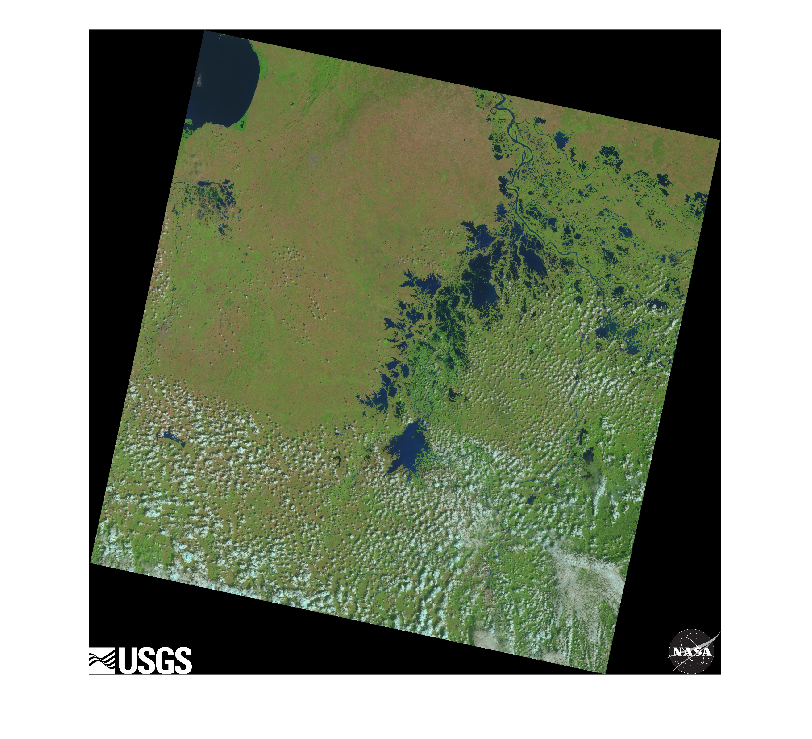

%Cargar la imagen original
a = imread ('../Test_Images/Image_1.jpg');
imshow(a)


%Rotacion de la imagen, valor hallado experimentalmente para las imagenes de landsat 8
he = imrotate(a,12, 'crop');

%Cambio a espacio de color lab y filtrado de capa l
lab_he = rgb2lab(he);
ab = lab_he(:,:,2:3);
ab = im2single(ab);

%Numero de clusters
nColors = 4;

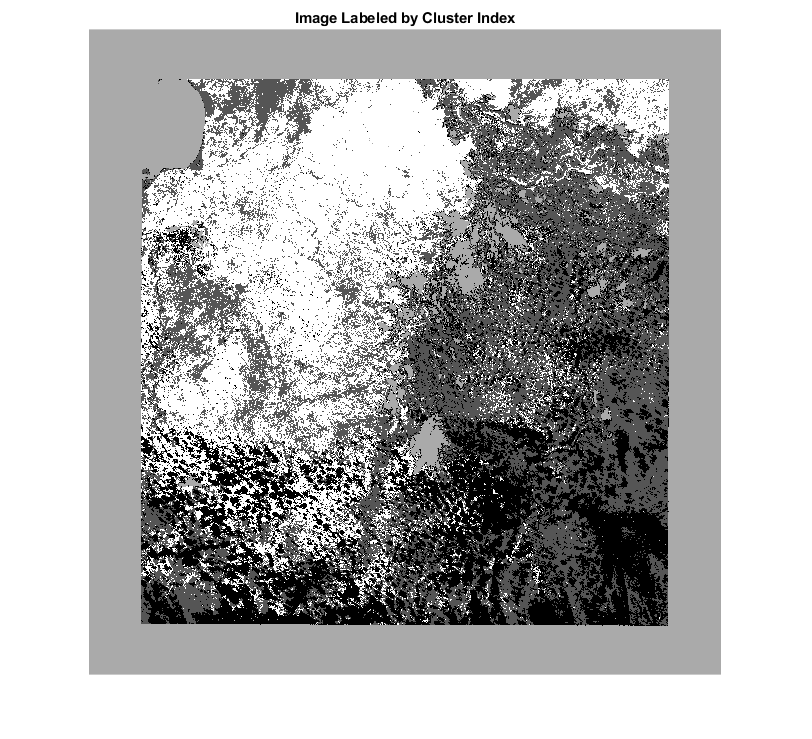

%Funcion para aplicar segmentacion mediante kmeans
% repeat the clustering 3 times to avoid local minima
pixel_labels = imsegkmeans(ab,nColors,'NumAttempts',3);

imshow(pixel_labels,[])
title('Image Labeled by Cluster Index');

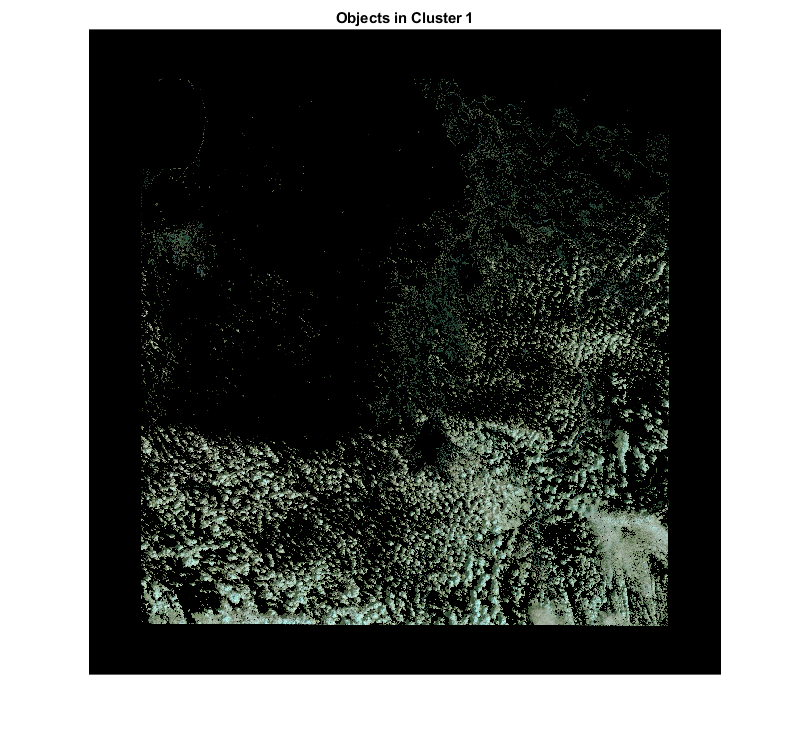

%Cluster 1
mask1 = pixel_labels==1;
cluster1 = he .* uint8(mask1);
% figure(1);
imshow(cluster1)
title('Objects in Cluster 1');

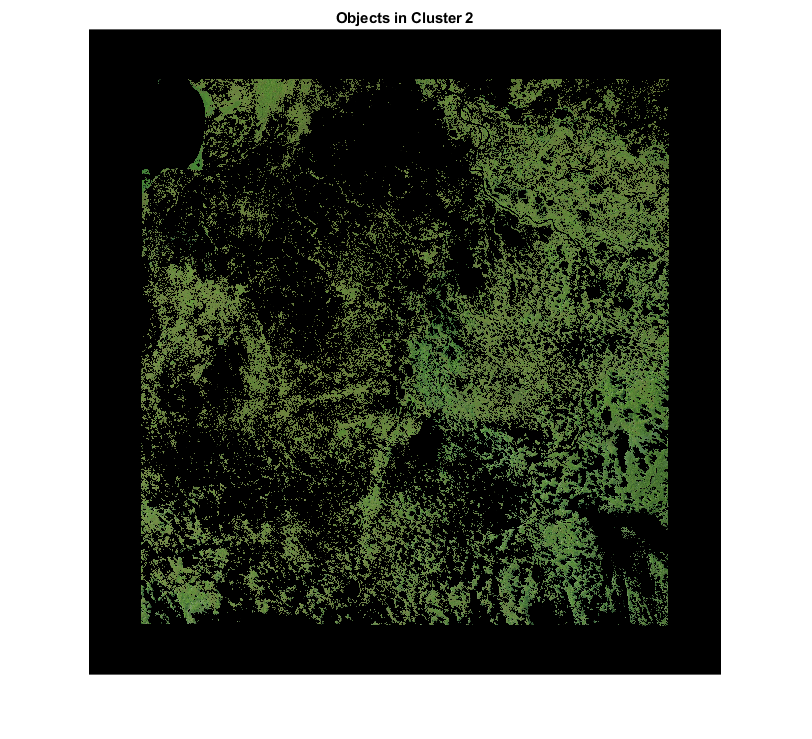

%Cluster 2
mask2 = pixel_labels==2;
cluster2 = he .* uint8(mask2);
% figure(2);
imshow(cluster2)
title('Objects in Cluster 2');

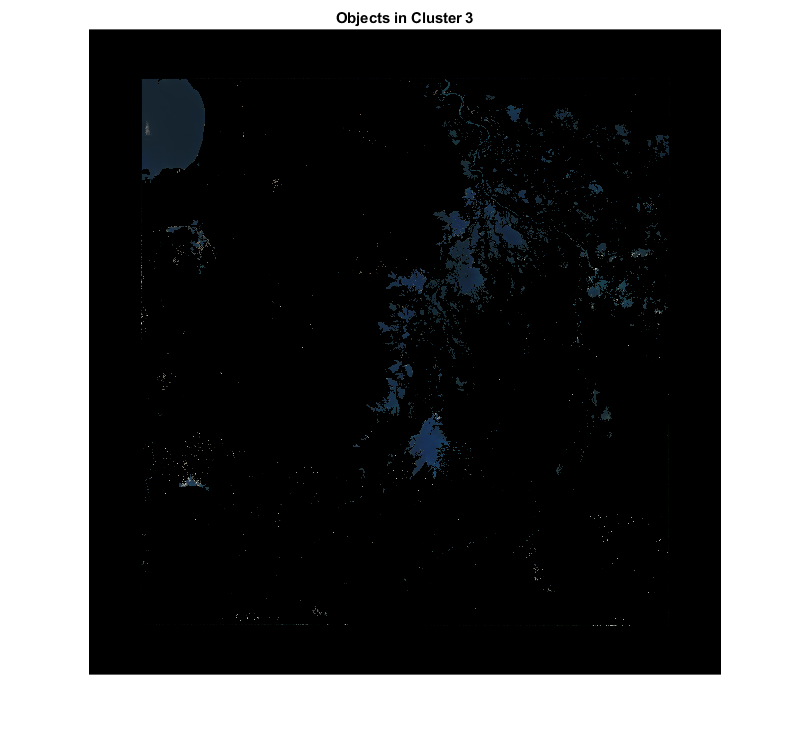

%Cluster 3
mask3 = pixel_labels==3;
cluster3 = he .* uint8(mask3);
% figure(3);
imshow(cluster3)
title('Objects in Cluster 3');

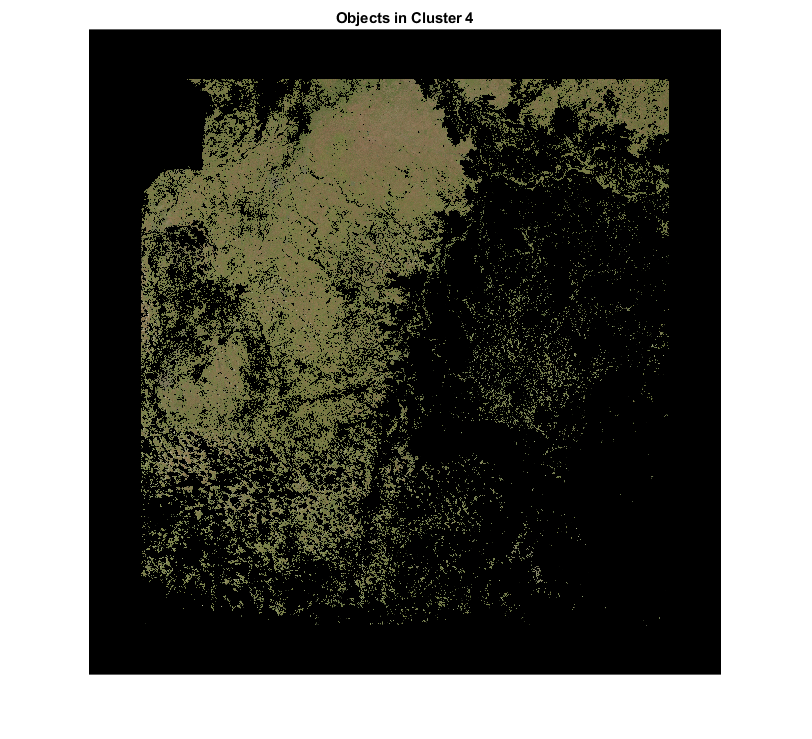

%Cluster 4
mask4 = pixel_labels==4;
cluster4 = he .* uint8(mask4);
% figure(4);
imshow(cluster4)
title('Objects in Cluster 4');